# Herramientas de MATLAB

### 17/10/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 8 y 9*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

#### Solución

`Repaso Punto 1, formulación de reglas simples & compuestas`

clear

f = @(x) (3 * exp(-x.^2) + sin(5/pi * x)) ./ log(x + 5);
a = -3; b = 2;

Isimple = ReglaPuntoMedio(f, a, b)

Isimple = 5.3920

tic
Ipropia = ReglaPuntoMedioPropia(f, a, b, 50)

Ipropia = 3.9257

toc

Elapsed time is 0.007315 seconds.


tic
Icompuesta = ReglaPuntoMedioCompuesta(f, a, b, 50)

Icompuesta = 3.9257

toc

Elapsed time is 0.007468 seconds.


`Repaso Punto 4, Funciones a trozos`

clear
syms V(t)
syms x real

V(t) = piecewise(0 <= t <= 10, 10*t^2 - 5*t, ...
                10 <= t <= 20, 1e3 - 5*t, ...
                10 <= t <= 30, 45*t + 21*(t - 20)^2)
tic

$$V(t) = \left\{ \begin{array}{cl} 10\,t^{2}-5\,t & \text{ if }t\in \left[0,10\right]\\ 1000-5\,t & \text{ if }t\in \left[10,20\right]\\ 45\,t+21\,{\left(t-20\right)}^{2} & \text{ if }t\in \left[10,30\right] \end{array}\right.$$

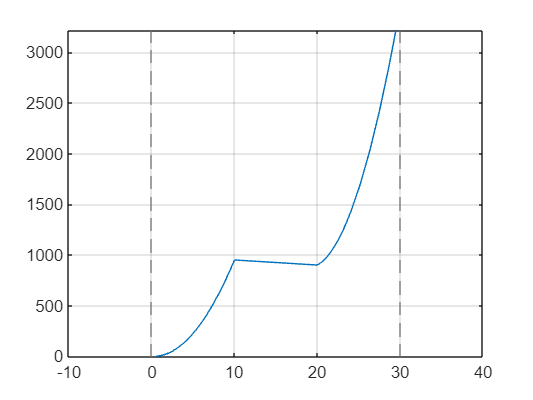

clf('reset')
fplot(V, [-10, 40])
grid on
toc

v(t) = (10*t^2 - 5*t) .* (0 <= t & t <= 10) + ...

Elapsed time is 0.363721 seconds.


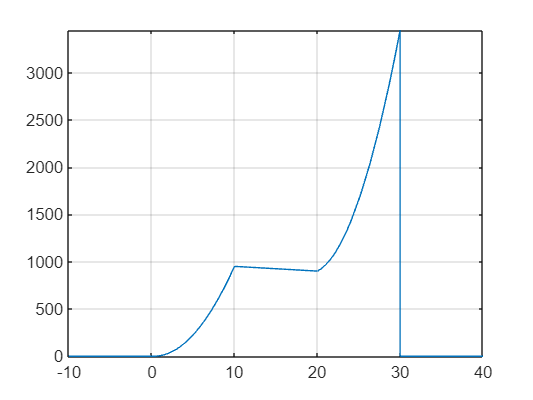

       (1e3 - 5*t) .* (10 < t & t <= 20) + ...
       (45*t + 21*(t - 20)^2) .* (20 < t & t <= 30);

v = matlabFunction(v);

tic
clf('reset')
fplot(v, [-10, 40])
grid on
toc

tic

Elapsed time is 3.450697 seconds.


IV = eval(traprl(V, 0, 30, 90))
toc

IV = 3.0589e+04

tic

Elapsed time is 0.937713 seconds.


Iv = traprl(v, 0, 30, 90)
toc

Iv = 3.0589e+04

Elapsed time is 0.003735 seconds.


#### Métodos / Rutinas

function aproxx = ReglaPuntoMedio(f, a, b)
% Blah, blah, blah, blah ...
% Input     - f @ Function Handle
%           - a Left Interval
%           - b Right Interval
% output    - aproxx Númeric Integral

h = (b - a) / 2;
x0 = a + h;

aproxx = 2 * h * feval(f, x0);

end

function aproxx = ReglaPuntoMedioPropia(f, a, b, n)
% Blah, blah, blah, blah ...
% Input     - f @ Function Handle
%           - a Left Interval
%           - b Right Interval
%           - n Número de subintervalos
% output    - aproxx Númeric Integral

if ~(rem(n, 2) == 0)
    error('Número de intervalos (n) debe ser par')
end

h = (b - a) / n;
aproxx = 0;         % Acumulador

for k = 1:n/2
    inicio = a + 2*h*(k - 1);
    fin = a + 2*h*k;

    aproxx = aproxx + ReglaPuntoMedio(f, inicio, fin);
end

end

function aproxx = ReglaPuntoMedioCompuesta(f, a, b, n)
% Blah, blah, blah, blah ...
% Input     - f @ Function Handle
%           - a Left Interval
%           - b Right Interval
%           - n Número de subintervalos
% output    - aproxx Númeric Integral

if rem(n, 2) == 1
    error('Número de intervalos (n) debe ser par')
end

h = (b - a) / n;
aproxx = 0;         % Acumulador

for j = 1:n/2
    x0 = a + (2*j - 1)*h;
    
    aproxx = aproxx + 2 * h * feval(f, x0);
end

end